clear; clc; rng(1);


M = 4;                       
N = 64;                      
P = 32;                      % Preamble uzunluğu
bps = log2(M);
SNRdB = 10;
SNRlin = 10^(SNRdB/10);
N0 = 1 / SNRlin;


h = (randn(2,1) + 1j*randn(2,1)) / sqrt(2); 
w = sqrt(N0/2) * (randn(N,1) + 1j*randn(N,1)); 


%% m-Sequence Preambl
n = 5; % Derece
poly = [5 3]; % Polinom: x^5 + x^3 + 1
L = 2^n - 1; % Periyot: 31
state = [1 0 0 0 0]; % Başlangıç durumu
m_seq = zeros(L, 1);
for i = 1:L
    m_seq(i) = state(end);
    feedback = mod(sum(state(poly)), 2); % XOR
    state = [feedback state(1:end-1)]; 
end
m_seq_bpsk = 2 * m_seq - 1; % BPSK
A = [m_seq_bpsk; 0]; 
A_tx = A; 



Kdata = N - P; 
txBits = randi([0 1], Kdata*bps, 1);
txSym = qammod(txBits, M, 'gray', 'UnitAveragePower', true, 'InputType', 'bit');


X_f = [A; txSym]; % Preamble + veri 
Y_f = h(1) * X_f(1:P) + w(1:P); 
Y_f = [Y_f; h(2) * X_f(P+1:end) + w(P+1:end)]; 

% gecikme ekle
numSymbols = 5; 
y_total = zeros(N, numSymbols);
y_total(:,3) = Y_f; % Preamble + veri, 3. sembole yerleştirildi

%% Korelasyon
[maxCorr, offset, metrics] = freqDomainCorrelation(y_total, A_tx, P);



fprintf('Başlangıç sembolü indeksi: %d\n', offset);

Başlangıç sembolü indeksi: 2


fprintf('Korelasyon metriği: %.4f\n', maxCorr);

Korelasyon metriği: 0.8232


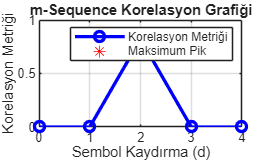


%% Korelasyon Grafiği
figure;
plot(0:numSymbols-1, metrics, 'b-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Sembol Kaydırma (d)');
ylabel('Korelasyon Metriği');
title('m-Sequence Korelasyon Grafiği');
grid on;
hold on;
plot(offset, maxCorr, 'r*', 'MarkerSize', 10); % Pik noktası
legend('Korelasyon Metriği', 'Maksimum Pik');
hold off;


%%Korelasyon Fonksiyonu (Matched Filter)
function [maxCorr, offset, metrics] = freqDomainCorrelation(y_total, A_tx, P)
    maxCorr = 0;
    offset = 0;
    metrics = zeros(1, size(y_total,2)); 
    epsilon = 1e-10; % Sıfıra bölme önleme
    for d = 0:size(y_total,2)-1 
        Y_pream = y_total(1:P, d+1); 
        corr_val = sum(conj(A_tx) .* Y_pream);
        norm_product = norm(A_tx)^2 * (norm(Y_pream)^2 + epsilon);
        metric = abs(corr_val)^2 / norm_product;
        metrics(d+1) = metric; 
        if metric > maxCorr
            maxCorr = metric;
            offset = d;
        end
    end
end